error_benign =     0.3894    0.6310    1.0049    0.7688    0.9470    0.4828    0.4625    0.4085


optrank_b = 3

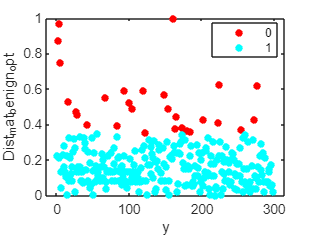

error_malignant =     0.2368    0.5375    0.4737    0.6832    0.5895    0.8414    0.4692    0.4901


optrank_m = 6

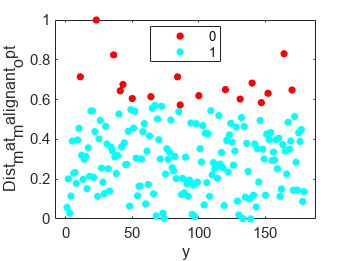

error_benign =     0.4331    0.3506    0.3458    0.4890    0.5213    0.2932    0.3187    0.5100


optrank_b = 5

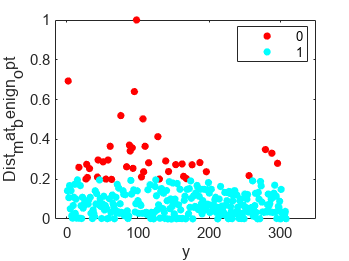

error_malignant =     1.4733    2.2822    0.7001    0.5174    0.6189    0.5737    1.5172    0.6423


optrank_m = 2

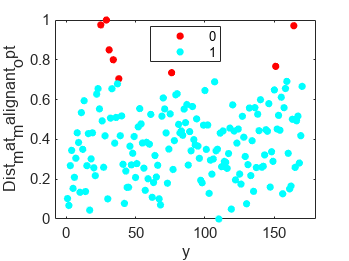

error_benign =     0.4067    0.5949    0.4402    1.0955    0.8193    0.9411    1.3528    0.0827


optrank_b = 7

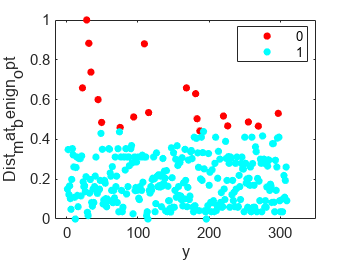

error_malignant =     1.2877    1.5490    0.4017    0.6769    1.7477    2.0173    1.7052    0.3802


optrank_m = 6

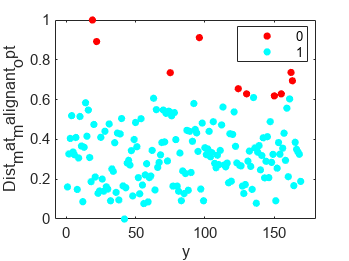

error_benign =     0.3493    1.0203    0.3646    0.2873    0.4614    0.2881    0.2440    0.2842


optrank_b = 2

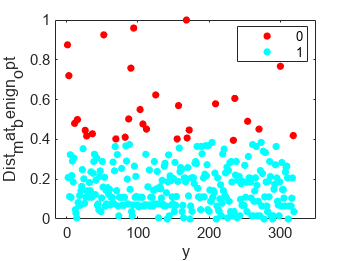

error_malignant =     0.5987    0.8888    0.2943    0.3848    1.5639    0.4911    0.5441    0.4147


optrank_m = 5

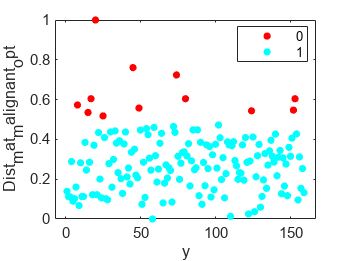

error_benign =     0.4996    1.0384    0.5002    0.3109    0.9302    0.7917    0.2084    0.1879


optrank_b = 2

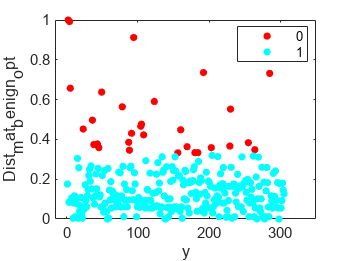

error_malignant =     1.1710    1.8904    0.7132    1.6876    0.2349    0.5240    0.2565    0.3332


optrank_m = 2

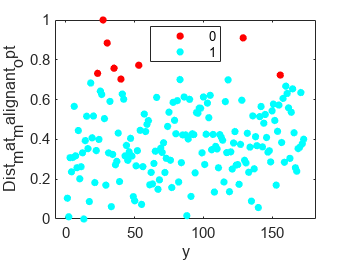

error_benign =     0.3065    0.3346    0.9245    0.3095    0.5095    1.1112    0.9411    1.2700


optrank_b = 8

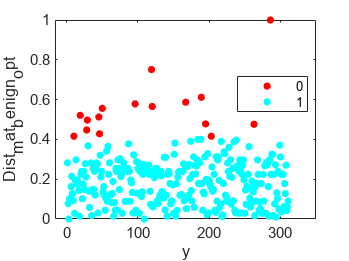

error_malignant =     1.6003    0.7881    0.7773    0.5151    2.6336    0.2834    0.6046    0.5762


optrank_m = 5

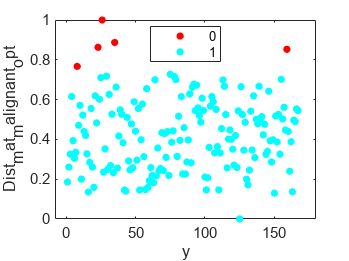

error_benign =     0.4491    0.4753    0.4176    0.3876    0.5767    0.6002    0.4301    0.7815


optrank_b = 8

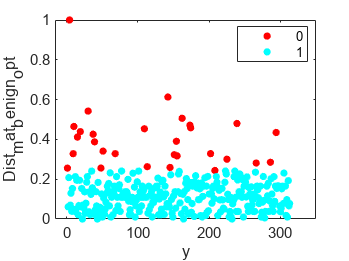

error_malignant =     3.3807    0.7709    1.3894    0.5223    0.5711    0.4544    0.7573    0.6446


optrank_m = 1

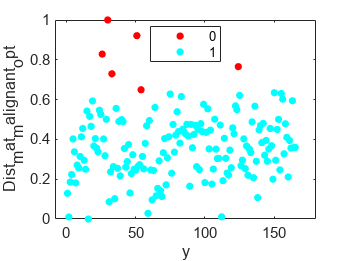

error_benign =     0.3655    0.5777    0.7336    0.9286    1.3183    2.7484    1.2143    0.8328


optrank_b = 6

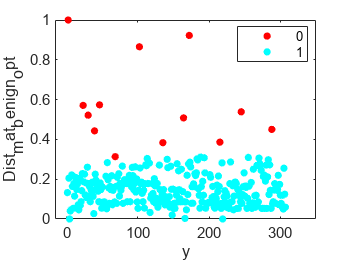

error_malignant =     1.4872    1.4977    0.6379    0.9848    0.5629    0.5853    2.1160    0.3118


optrank_m = 7

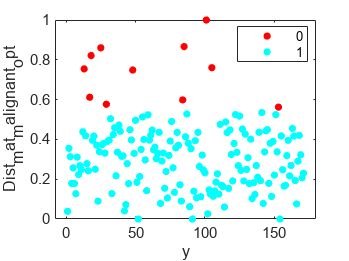

error_benign =     0.4700    0.6891    0.8903    1.0866    1.0652    2.3963    1.0037    0.5481


optrank_b = 6

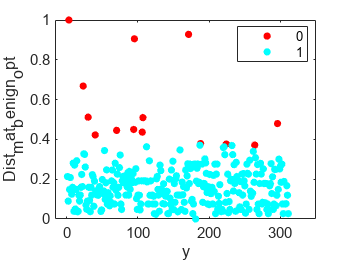

error_malignant =     3.4970    1.1831    0.3187    0.8049    0.4857    0.9126    0.5912    0.4708


optrank_m = 1

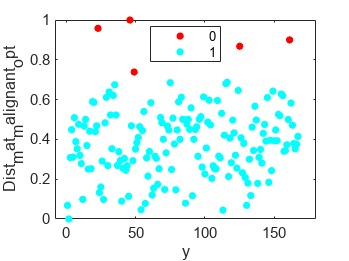

error_benign =     0.7540    1.1075    1.3440    1.4986    1.2301    0.7222    0.5592    0.4082


optrank_b = 4

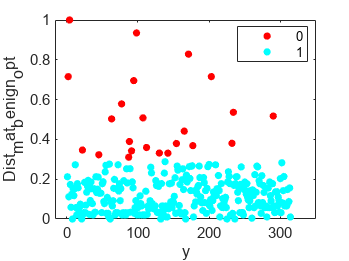

error_malignant =     1.2651    0.5411    1.0258    0.5109    0.7143    0.4332    0.3355    0.4138


optrank_m = 1

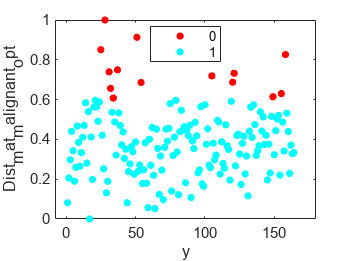

for j = [1,2,3,4,5,6,7,8,9,10]
    figure

    splitfolder=strcat('split',num2str(j));
    per =[10];%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('cell_sample_noisy_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        benign=File(File(:,10)==2,1:9);
        T_benign=benign.';
        malignant=File(File(:,10)==4,1:9);
        T_malignant=malignant.';

        folder_l1=strcat('ACE_dist_8optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3,4,5,6,7,8];

        error_benign = nan(size(ranks));
        numbenign=length(T_benign);
        Dist_mat_benign_array=nan(length(ranks),numbenign);
        threshold_rank_b=nan(size(ranks));
        elbow_indx_rank_b=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

            T_benign_temp=T_benign;
            Dist_mat_benign=[];


            BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
            for k = 1 : numbenign
                A=T_benign(:,k);
                Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_benign,[],"all");
            max_val=max(Dist_mat_benign,[],"all");
            Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
            Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


            Dist_mat_benign_array(i,:)=Dist_mat_benign;
            [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");


            [elbow_b_err_angle,elbow_indx_b]=knee_pt_angle((Dist_mat_benign_asc));

            error_benign(i)=elbow_b_err_angle;
            threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
            elbow_indx_rank_b(i)=elbow_indx_b;

% 
%             figure
%             plot((Dist_mat_benign_asc),'-s',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance Benign Asc for Rank",num2str(i)])
%             title(['Rank =',num2str(i) ])


        end

        
        error_benign

        [~,optrank_b]= max(error_benign)

        Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
        threshold_dist_b= threshold_rank_b(optrank_b);
        elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);

        ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
        ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);


        cluster_b=zeros(size(Dist_mat_benign_opt));
        cluster_b(ind_I_b)=1;
        figure
        y= 1:1:length(benign);
        numGroups = length(unique(cluster_b));
        gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))
% 
%         figure
%         plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b_opt),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("index")
%         ylabel(["Distance Benign Asc for opt rank" ,num2str(optrank_b)])
%         title(['Rank opt for Benign =',num2str(optrank_b),"Split=",num2str(j)])
%         ind_O_b;


        T_benign_temp(:,ind_O_b)=[];
        length(T_benign_temp);

        Final_benign=T_benign_temp';
        Final_benign(:,10)=2;

    end
    %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    nummalignant=length(T_malignant);
    error_malignant=nan(size(ranks));
    Dist_mat_mal_array=nan(length(ranks),nummalignant);
    threshold_rank_m=nan(size(ranks));
    elbow_rank_m=nan(size(ranks));


    for i=ranks
        %fprintf("Rank is %i \n", i) %i);

        T_malignant_temp=T_malignant;
        Dist_mat_malignant=[];

        BF_malignant=l1pca_BF(T_malignant,i,1,10,10,'');
        for k = 1 : nummalignant
            A=T_malignant(:,k);
            Dist_mat_malignant(k)=norm((A-(BF_malignant*BF_malignant.'*A)),1);
            k;
        end

        Dist_mat_malignant;
        min_val=min(Dist_mat_malignant,[],"all");
        max_val=max(Dist_mat_malignant,[],"all");
        Dist_mat_malignant= Dist_mat_malignant -min_val;%]/[max_val-min_val]
        Dist_mat_malignant=Dist_mat_malignant /(max_val-min_val);
        Dist_mat_mal_array(i,:)=Dist_mat_malignant;

        [Dist_mat_malignant_asc,Indx_m]=sort(Dist_mat_malignant,"ascend");


        [elbow_m_err_angle,elbow_indx_m]=knee_pt_angle((Dist_mat_malignant_asc));

        error_malignant(i)=elbow_m_err_angle;
        threshold_rank_m(i)=Dist_mat_malignant_asc(elbow_indx_m);
        elbow_rank_m(i)=elbow_indx_m;

%         figure
%         plot((Dist_mat_malignant_asc),'-*',"MarkerIndices",(elbow_indx_m),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("Index")
%         ylabel("Distance Malignant Asc")
%         title(["Rank =", num2str(i)])


    end
    error_malignant
    [~,optrank_m]= max(error_malignant)

    Dist_mat_malignant_opt=Dist_mat_mal_array(optrank_m,:);
    threshold_dist_m= threshold_rank_m(optrank_m);
    elbow_indx_m_opt=elbow_rank_m(optrank_m);

    ind_O_m=find(Dist_mat_malignant_opt>threshold_dist_m);
    ind_I_m=find(Dist_mat_malignant_opt<=threshold_dist_m);

    cluster_m=zeros(size(Dist_mat_malignant_opt));
    cluster_m(ind_I_m)=1;

    figure
    y= 1:1:length(malignant);
    numGroups = length(unique(cluster_m));
    gscatter(y,Dist_mat_malignant_opt,cluster_m,hsv(numGroups))

%     figure
%     plot(sort(Dist_mat_malignant_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_m_opt),'MarkerFaceColor','red','MarkerSize',10 )
%     xlabel("Index")
%     ylabel("Distance Malignant Asc for opt rank")
%     title(["Opt Rank for Malignant=",num2str(optrank_m),"Split=",num2str(j)])

    ind_O_m;


    T_malignant_temp(:,ind_O_m)=[];
    length(T_malignant_temp);

    Final_malignant=T_malignant_temp';
    Final_malignant(:,10)=4;


    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
    cd (splitfolder)
    cd (folder)

    cd (folder_l1)

    L1pca_file=(horzcat(Final_benign.',Final_malignant.')).';

    L1pca_file = array2table(L1pca_file);
    L1pca_file.Properties.VariableNames(1:10)=  {'Clump','UnifSize','UnifShape','MargAdh','SingEpiSize','BareNuc','BlandChrom','NormNucl','Mit','Class'};
    filel1pca=strcat('cell_sample_noisy_per',num2str(percent),'_ACE_l1pca.csv');
    writetable(L1pca_file,filel1pca);

end